## eidAnalyisis overview

% load tbl
tbl = compute_tbl(0);   

tbl(1:3, :)

## get 15 unique datasets

tbl.sum = cellfun(@(x) sum(x, 2), tbl.rawData, 'UniformOutput',false);
tbl.sum_mean = cellfun(@mean, tbl.sum);
tbl.sum_std = cellfun(@std, tbl.sum);
ANM = 0;
IHC = 0;
cellType = 1;
intervalType = 2;
data = getOneEntry(tbl, ANM, IHC, cellType, intervalType, 0, 0, -2, 0)
anm = 3
%plot_SumMeCP2(data(anm,:), [0,4])

ANM = 0;
IHC = 0;
cellType = 1;
intervalType = 2;
data = getOneEntry(tbl, ANM, IHC, cellType, intervalType)

y = reshape(data.sum, 3, 5);
e = reshape(data.sum_std, 3, 5);
g = reshape(data.IHC, 3, 5);
g = g(:,1);
l = reshape(data.ANM, 3, 5);
l = l(1,:)
y2 = cellfun(@mean, y)
barweb(y2,e, [],g, [], 'Stain positive nucleui', 'Sum MeCP2-JF dyes (uM)', [], [], l, [], 'axis');

mean(y2,2)

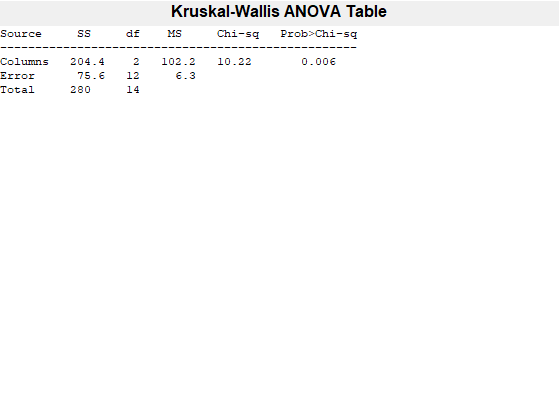

[p,ttt,stats] = anova1(y2');

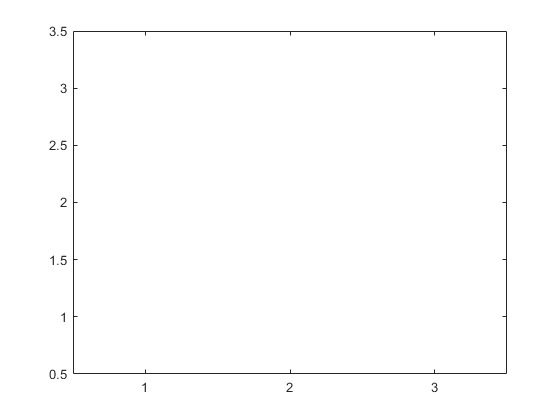

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


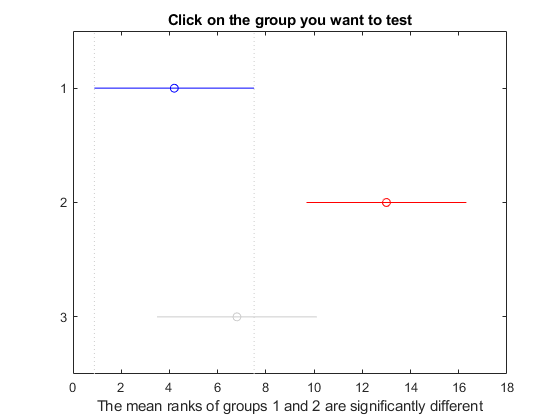

results =             1            2      -15.429         -8.8       -2.171    0.0052932
            1            3       -9.229         -2.6        4.029       0.6281
            2            3     -0.42899          6.2       12.829      0.07252


means =           4.2            2
           13            2
          6.8            2


[results,means] = multcompare(stats)

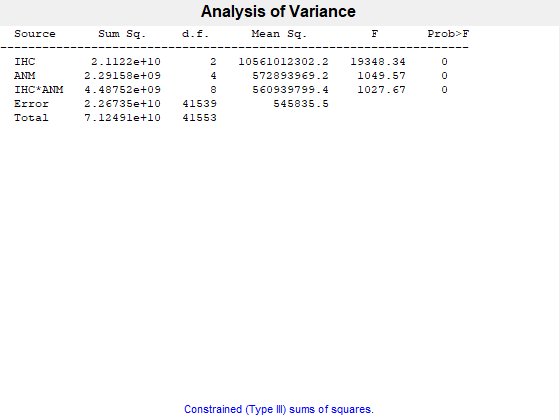

sum_all = cell2mat(data.sum);
g_ANM = {};
g_IHC= {};
for i = 1:height(data)
    count = data.count(i);
    ANM = data.ANM{i};
    IHC = data.IHC{i};
    g_ANM = cat(1, g_ANM, repmat({ANM}, count, 1));
    g_IHC = cat(1, g_IHC, repmat({IHC}, count, 1));
end
[p,tbl22, stats] = anovan(sum_all,{g_IHC g_ANM},'model','full','varnames',{'IHC','ANM'});

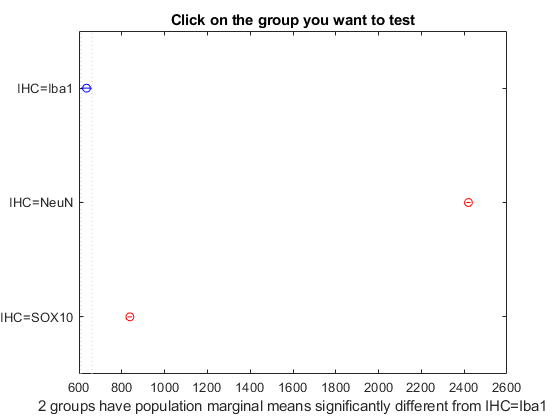

[results, m] = multcompare(stats, 'Dimension',1);

close all
f = figure();
f.Color='w'
violinplot(sum_all./1000, g_IHC);
ylabel('Sum MeCP2-HT-JF dyes (uM)')
% export_fig('SumAllViolin.eps')

violinplot( )